CGO_st.name='CGO'; 
CGO_st.lat=-40.68;
CGO_st.lon=144.69;
CGO_st.alt=94;
CGO_st.env='coast';
CGO_st.footp='RB';

MAAP=table2timetable(MAAPdata);
Neph=table2timetable(Nephall);
% % sum(MAAP.numflag>0)
% % figure
% % plot(MAAP.DateGMThhmm,MAAP.numflag,'.b');
% % hold on;
% % plot(Neph.DateGMThhmm,Neph.flag,'.r');
% % %flag==1

% remove NAN
MAAP.abs670(MAAP.numflag>0.99)=NaN;
Neph.RH_int(Neph.flag>0.9)=NaN;
Neph.sc450(Neph.flag>0.9)=NaN;
Neph.sc525(Neph.flag>0.9)=NaN;
Neph.sc635(Neph.flag>0.9)=NaN;
%remove not used variable
namesM=fieldnames(MAAP);
c=strcmp(namesM,'abs670')==1 | strcmp(namesM,'Properties')==1 |startsWith(namesM,["D";"V"]) ;
NM=namesM(~c);
for i=1:length(NM)
    MAAP.(NM{i})=[];
end

namesN=fieldnames(Neph);
c=strcmp(namesN,'sc450')==1 |strcmp(namesN,'sc525')==1|strcmp(namesN,'sc635')==1 | strcmp(namesN,'Properties')==1 |startsWith(namesN,["D";"V";"R"]) ;
NN=namesN(~c);
for i=1:length(NN)
    Neph.(NN{i})=[];
end

CGO_rd=timetable(MAAP.DateGMThhmm);
CGO_rd.Time=MAAP.DateGMThhmm;
CGO_rd.BaR=MAAP.abs670;
CGO_rd=synchronize(CGO_rd,Neph);
CGO_rd.Properties.VariableNames={'BaR_A';'U';'BsB_S';'BsG_S';'BsR_S'};


datevec(CGO_rd.Time(1))

ans =         2008           1           1           0           0           0


datevec(CGO_rd.Time(end))

ans =         2018          12          31          23           0           0


 prctile(CGO_rd.U,[5 50 95])

ans =    20.1900   30.8400   40.2500


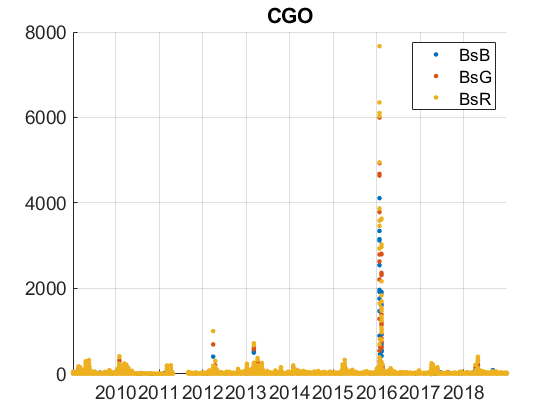

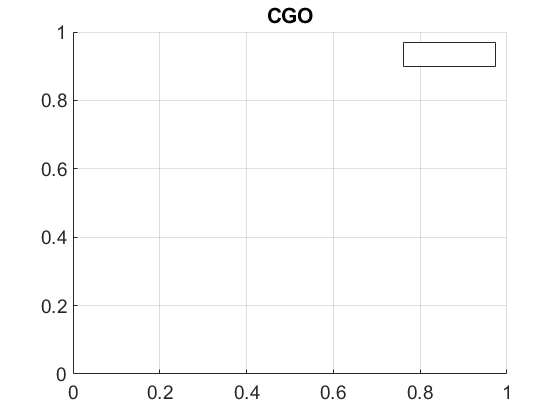

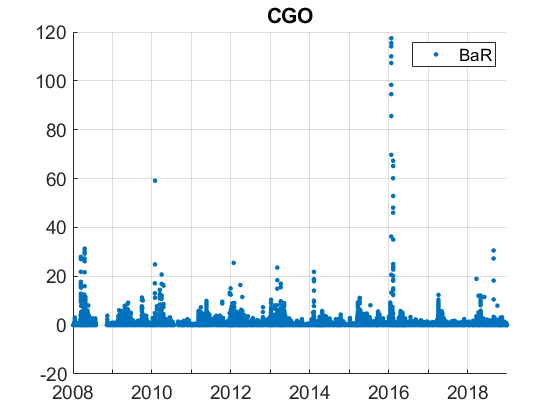

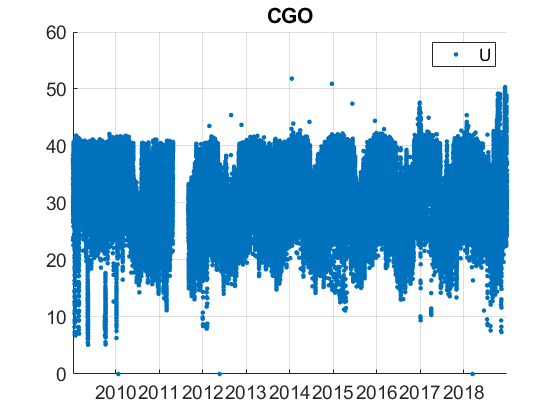

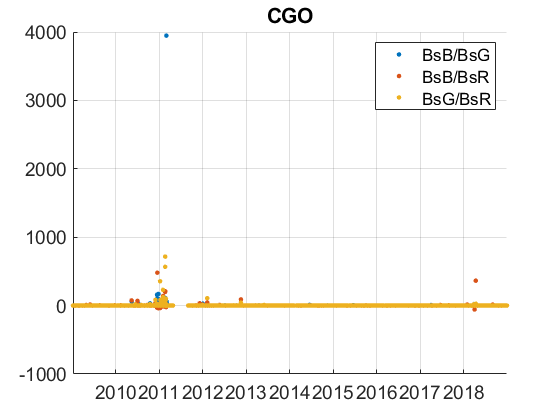

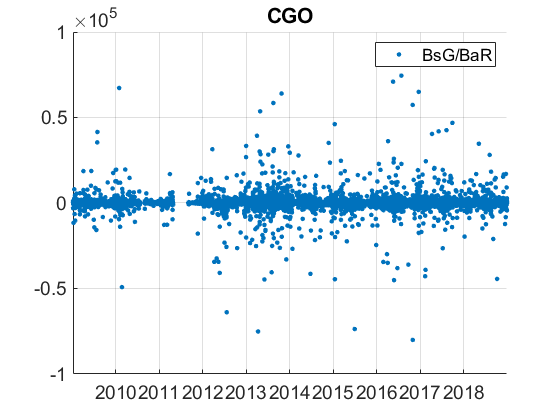

plotFigControl(CGO_rd,CGO_st.name);

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
CGO_cal=compute_exp_SSA(CGO_rd,lambdaSC, lambdaAE);
plotFigControl_cal(CGO_cal, CGO_st.name);

% fait la mediane journalière
CGO_rdd=retime(CGO_rd,'daily',@nanmedian);
CGO_cal=compute_exp_SSA(CGO_rdd,lambdaSC, lambdaAE);

% one size cut
%RH ok < 50% and no trend
%problem with neph in 2010-2012

CGO_tr=CGO_rdd;
CGO_tr.y=year(CGO_tr.Time);
% begin at the beginning of a year:abs:2008, scat:2009
%end: 2018
P=timerange('2008-01-01','2019-01-01');
CGO_tr=CGO_tr(P,:);

%no variables to delete
%no neph data in 2009 at all
%no need to analyse dry neph

%neph problems 2010-2012:
% following answer to questions:invalid: 24.5.2010-1.8.2010 ,
% invalid october 2010-7.3.2011 and invalid: 28.5.2011-21.2.2012
p1=timerange('2010-05-24','2011-03-07');
p3=timerange('2011-04-29','2012-02-21');

names=fieldnames(CGO_tr);
c= startsWith(names,["Bs";"Bbs"]);
N=names(c);
for i=1:length(N)
   CGO_tr.(N{i})(p1)=NaN;
   CGO_tr.(N{i})(p3)=NaN;
end

CGO_cal2=compute_exp_SSA(CGO_tr,lambdaSC, lambdaAE);
CGO_tr=outerjoin(CGO_tr, CGO_cal2);

%compute trend only on green
CGO_tr.BsB_S=[];
CGO_tr.BsR_S=[];


%compute exp only on br
% remove calibration problem
% % pp1=timerange('2018-11-15','2019-01-01');
% % pp2=timerange('2016-03-07','2016-11-11');
pp3=timerange('2013-02-26','2013-06-03');
CGO_tr.expS_br3(pp3)=NaN;
CGO_tr.expS_br=CGO_tr.expS_br3;
CGO_tr.expS_br3=[];
CGO_tr.expS_gr3=[];
CGO_tr.expS_bg3=[];

%after trend analysis, decide if trend or only dlm should be used!!
CGO_result= all_trend_STN(CGO_tr,CGO_st); 

CGO_result_D=CGO_result;